clear all
clc

load('data_SSM/zzd.mat','zzd')
load('data_SSM/t.mat','t')
load('data_SSM/y_exprm.mat','y_exprm')
zzd_ssm = zzd;
t_ssm   = t;   t_ssm   = [0, t_ssm];
y_exprm_ssm = y_exprm;
y_exprm_ssm = y_exprm_ssm - y_exprm_ssm(1,:);

load('data_POD6/zzd.mat','zzd')
load('data_POD6/t.mat','t')
load('data_POD6/y_exprm.mat','y_exprm')
zzd_pod6 = zzd;
t_pod6   = t;  t_pod6   = [0, t_pod6];
y_exprm_pod6 = y_exprm;
y_exprm_pod6 = y_exprm_pod6 - y_exprm_pod6(1,:);


load('data_POD26/zzd.mat','zzd')
load('data_POD26/t.mat','t')
load('data_POD26/y_exprm.mat','y_exprm')
zzd_pod26 = zzd;
t_pod26   = t;  t_pod26   = [0, t_pod26];
y_exprm_pod26 = y_exprm;
y_exprm_pod26 = y_exprm_pod26 - y_exprm_pod26(1,:);


% figure; hold on
% plot(t_ssm(2:end),  zzd_ssm(1,:),'k-',LineWidth=4,DisplayName='Target')
% plot(t_ssm,  y_exprm_ssm(:,1),'b--',LineWidth=4,DisplayName='SSM$\mathcal{O}$(6)-MPC')
% plot(t_pod6, y_exprm_pod6(:,1),'g-.',LineWidth=4,DisplayName='POD$\mathcal{O}$(6)-MPC')
% plot(t_pod26,y_exprm_pod26(:,1),'m:',LineWidth=4,DisplayName='POD$\mathcal{O}$(26)-MPC')
% xlim([t_ssm(1)-0.001,t_ssm(end)])
% % grid on
% xlabel('$t$/(s)',Interpreter='latex',FontSize=24)
% ylabel('X/(mm)',Interpreter='latex',FontSize=24)
% legend('show',Interpreter='latex',fontsize=16)
% plot_setting
% 
% figure; hold on
% plot(t_ssm(2:end),  zzd_ssm(2,:),'k-',LineWidth=4,DisplayName='Target')
% plot(t_ssm,  y_exprm_ssm(:,2),'b--',LineWidth=4,DisplayName='SSM$\mathcal{O}$(6)-MPC')
% plot(t_pod6, y_exprm_pod6(:,2),'g-.',LineWidth=4,DisplayName='POD$\mathcal{O}$(6)-MPC')
% plot(t_pod26,y_exprm_pod26(:,2),'m:',LineWidth=4,DisplayName='POD$\mathcal{O}$(26)-MPC')
% xlim([t(1)-0.001,t(end)])
% % grid on
% xlabel('$t$/(s)',Interpreter='latex',FontSize=24)
% ylabel('Y/(mm)',Interpreter='latex',FontSize=24)
% legend('show',Interpreter='latex',fontsize=16)
% plot_setting
% 
% figure; hold on
% plot(zzd_ssm(1,:),zzd_ssm(2,:),'k-',LineWidth=4,DisplayName='Target')
% plot(y_exprm_ssm(:,1),y_exprm_ssm(:,2),'b--',LineWidth=4,DisplayName='SSM$\mathcal{O}$(6)-MPC')
% plot(y_exprm_pod6(:,1),y_exprm_pod6(:,2),'g-.',LineWidth=4,DisplayName='POD$\mathcal{O}$(6)-MPC')
% plot(y_exprm_pod26(:,1),y_exprm_pod26(:,2),'m:',LineWidth=4,DisplayName='POD$\mathcal{O}$(26)-MPC')
% % xlim([min(zzd__(1,:))-3,max(zzd__(1,:))+3])
% % ylim([min(zzd__(1,:))-3,max(zzd__(1,:))+3])
% grid on
% xlabel('$X$/(mm)',Interpreter='latex',FontSize=24)
% ylabel('$Y$/(mm)',Interpreter='latex',FontSize=24)
% legend('show',Interpreter='latex',fontsize=14)
% plot_setting2

## Integrated Squared Error (ISE)

errs_ssm = (y_exprm_ssm(2:end,:) - zzd_ssm') / 1000;  % errs_ssm = errs_ssm./1000;
ISE_ssm  = 0;
for i = 1:size(errs_ssm, 1)
    ISE_ssm = ISE_ssm + sum((errs_ssm(i,1:2)).^2);
end
ISE_ssm

ISE_ssm = single
4.9992e-04


errs_pod6 = (y_exprm_pod6(2:end,:) - zzd_pod6') / 1000; % errs_pod6 = errs_pod6./1000;
ISE_pod6  = 0;
for j = 1:size(errs_pod6, 1)
    ISE_pod6 = ISE_pod6 + sum((errs_pod6(j,1:2)).^2);
end
ISE_pod6

ISE_pod6 = single
0.0013


errs_pod26 = (y_exprm_pod26(2:end,:) - zzd_pod26') / 1000; % errs_pod26 = errs_pod26./1000;
ISE_pod26  = 0;
for k = 1:size(errs_pod26, 1)
    ISE_pod26 = ISE_pod26 + sum((errs_pod26(k,1:2)).^2);
end
ISE_pod26

ISE_pod26 = single
8.0777e-04


rel_ISE_ssm   = 0;
rel_ISE_pod6  = (ISE_pod6 - ISE_ssm)/ISE_ssm  .* 100

rel_ISE_pod6 = single
164.8472

rel_ISE_pod26 = (ISE_pod26 - ISE_ssm)/ISE_ssm .* 100

rel_ISE_pod26 = single
61.5783

rel_ISEs  = [rel_ISE_ssm, round(rel_ISE_pod6), round(rel_ISE_pod26)];

% figure; hold on
% plot_setting3
% subplot(1,4,1); hold on;
% h1 = plot(zzd_ssm(1,:),zzd_ssm(2,:),'k-',LineWidth=6,DisplayName='Target')
% h2 = plot(y_exprm_ssm(:,1),y_exprm_ssm(:,2),'b--',LineWidth=6,DisplayName='SSM$\mathcal{O}$(6)-MPC')
% scatter(0,0,50,'ro','filled')
% xlabel('$X$/(mm)',Interpreter='latex',FontSize=12)
% ylabel('$Y$/(mm)',Interpreter='latex',FontSize=12)
% xlim([-17.5, 12.5])
% ylim([-17.5, 12.5])
% box on
% 
% subplot(1,4,2); hold on;
% plot(zzd_ssm(1,:),zzd_ssm(2,:),'k-',LineWidth=6,DisplayName='Target')
% h3 = plot(y_exprm_pod6(:,1),y_exprm_pod6(:,2),'g-.',LineWidth=6,DisplayName='POD$\mathcal{O}$(6)-MPC')
% scatter(0,0,50,'ro','filled')
% xlabel('$X$/(mm)',Interpreter='latex',FontSize=12)
% ylabel('$Y$/(mm)',Interpreter='latex',FontSize=12)
% xlim([-17.5, 12.5])
% ylim([-17.5, 12.5])
% box on
% 
% subplot(1,4,3); hold on;
% plot(zzd_ssm(1,:),zzd_ssm(2,:),'k-',LineWidth=6,DisplayName='Target')
% h4 = plot(y_exprm_pod26(:,1),y_exprm_pod26(:,2),'m:',LineWidth=6,DisplayName='POD$\mathcal{O}$(26)-MPC')
% scatter(0,0,50,'ro','filled')
% xlabel('$X$/(mm)',Interpreter='latex',FontSize=12)
% ylabel('$Y$/(mm)',Interpreter='latex',FontSize=12)
% xlim([-17.5, 12.5])
% ylim([-17.5, 12.5])
% box on
% 
% subplot(1,4,4); hold on;
% % x_labels = {['SSM','\\\\','(6D)'], ['POD','\\\\','(6D)'], ['POD','\\\\','(26D)']};  % x轴标签
% x_labels = {'SSM(6D)', 'POD(6D)', 'POD(26D)'};  % x轴标签
% box on
% ylim([0, 180])
% ylabel('Relative ISE ($\%$)',Interpreter='latex',FontSize=12)
% h = bar(x_labels, rel_ISEs);
% h.FaceColor = 'flat';
% h.EdgeColor = 'none';
% h.CData = [
%     0 0 1;   % 第1个柱子颜色（蓝）
%     0 1 0;   % 第2个柱子颜色（红）
%     1 0 1];  % 第3个柱子颜色（绿）
% ax = gca;  % 获取当前坐标轴句柄
% ax.TickLabelInterpreter = 'latex';
% ax.FontSize = 12;
% 
% x_pos = h.XData;  % 柱子的x坐标（自动生成，与标签对应）
% y_height = h.YData;  % 柱子的高度（即rel_ISEs的值）
% 
% 
% % 在柱子中心上方添加文本
% text(x_pos(1), ...       % x坐标（柱子位置）
%      y_height(1), ...    % y坐标（柱子高度，文本将放在此高度上方）
%      '$\textbf{Baseline}$', ...       % 文本内容
%      'HorizontalAlignment', 'center', ...  % 水平居中
%      'VerticalAlignment', 'bottom', ...     % 垂直对齐在柱子顶部
%      'FontSize', 12, ...                    % 字体大小
%      'Color', 'black',...
%      'Interpreter', 'latex');                     % 文本颜色
% text(x_pos(2), ...       % x坐标（柱子位置）
%      y_height(2), ...    % y坐标（柱子高度，文本将放在此高度上方）
%      '$\textbf{165\%}$', ... %[num2str(rel_ISEs(2)), '$\%$'], ...       % 文本内容
%      'HorizontalAlignment', 'center', ...  % 水平居中
%      'VerticalAlignment', 'bottom', ...     % 垂直对齐在柱子顶部
%      'FontSize', 12, ...                    % 字体大小
%      'Color', 'black',...
%      'Interpreter', 'latex');                     % 文本颜色
% text(x_pos(3), ...       % x坐标（柱子位置）
%      y_height(3), ...    % y坐标（柱子高度，文本将放在此高度上方）
%      '$\textbf{62\%}$', ... %[num2str(rel_ISEs(3)), '$\%$'], ...       % 文本内容
%      'HorizontalAlignment', 'center', ...  % 水平居中
%      'VerticalAlignment', 'bottom', ...     % 垂直对齐在柱子顶部
%      'FontSize', 12, ...                    % 字体大小
%      'Color', 'black',...
%      'Interpreter', 'latex');                     % 文本颜色
% 
% 
% legend_handles = [h1; h2; h3; h4];
% legend_labels = {'Target'; 'SSM(6D)'; 'POD(6D)'; 'POD(26D)'};
% 
% % 创建底部图例
% hLegend = legend(legend_handles, legend_labels, ...
%        'Location', 'west', ...  % 底部外侧
%        'Orientation', 'horizontal', ...  % 水平排列 horizontal
%        'NumColumns', 4, ...'NumColumns', 4, ...              % 5 列显示
%        'FontSize', 12,...
%        'Interpreter', 'latex',...
%        'IconColumnWidth', 60);                  % 字体大小

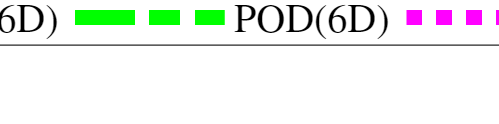

figure;
tiledlayout(1, 4, 'TileSpacing', 'tight', 'Padding', 'tight');
hold on;
plot_setting3;

% 第一个子图
nexttile;
hold on;
h1 = plot(zzd_ssm(1,:), zzd_ssm(2,:), 'k-', 'LineWidth', 6, 'DisplayName', 'Target');
h2 = plot(y_exprm_ssm(:,1), y_exprm_ssm(:,2), 'b--', 'LineWidth', 6, 'DisplayName', 'SSM$\mathcal{O}$(6)-MPC');
scatter(0, 0, 50, 'ro', 'filled');
xlabel('$X$/(mm)', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('$Y$/(mm)', 'Interpreter', 'latex', 'FontSize', 16);
xlim([-17.5, 12.5]);
ylim([-17.5, 12.5]);
box on;

% 第二个子图
nexttile;
hold on;
plot(zzd_ssm(1,:), zzd_ssm(2,:), 'k-', 'LineWidth', 6, 'DisplayName', 'Target');
h3 = plot(y_exprm_pod6(:,1), y_exprm_pod6(:,2), 'g-.', 'LineWidth', 6, 'DisplayName', 'POD$\mathcal{O}$(6)-MPC');
scatter(0, 0, 50, 'ro', 'filled');
xlabel('$X$/(mm)', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('$Y$/(mm)', 'Interpreter', 'latex', 'FontSize', 16);
xlim([-17.5, 12.5]);
ylim([-17.5, 12.5]);
box on;

% 第三个子图
nexttile;
hold on;
plot(zzd_ssm(1,:), zzd_ssm(2,:), 'k-', 'LineWidth', 6, 'DisplayName', 'Target');
h4 = plot(y_exprm_pod26(:,1), y_exprm_pod26(:,2), 'm:', 'LineWidth', 6, 'DisplayName', 'POD$\mathcal{O}$(26)-MPC');
scatter(0, 0, 50, 'ro', 'filled');
xlabel('$X$/(mm)', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('$Y$/(mm)', 'Interpreter', 'latex', 'FontSize', 16);
xlim([-17.5, 12.5]);
ylim([-17.5, 12.5]);
box on;

% 第四个子图（柱状图）
nexttile;
hold on;
box on;
ylim([0, 180]);
ylabel('Relative ISE ($\%$)', 'Interpreter', 'latex', 'FontSize', 16);
x_labels = {'SSM(6D)', 'POD(6D)', 'POD(26D)'};
h = bar(x_labels, rel_ISEs);
h.FaceColor = 'flat';
h.EdgeColor = 'none';
h.CData = [0 0 1; 0 1 0; 1 0 1];  % 蓝色、绿色、品红色

ax = gca;
ax.TickLabelInterpreter = 'latex';
ax.FontSize = 12;

% 在柱子上方添加文本
x_pos = h.XData;
y_height = h.YData;
text(x_pos(1), y_height(1), '$\textbf{Baseline}$', ...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', ...
    'FontSize', 16, 'Color', 'black', 'Interpreter', 'latex');
text(x_pos(2), y_height(2), '$\textbf{165\%}$', ...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', ...
    'FontSize', 16, 'Color', 'black', 'Interpreter', 'latex');
text(x_pos(3), y_height(3), '$\textbf{62\%}$', ...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', ...
    'FontSize', 16, 'Color', 'black', 'Interpreter', 'latex');

% 创建底部图例
legend_handles = [h1; h2; h3; h4];
legend_labels = {'Target'; 'SSM(6D)'; 'POD(6D)'; 'POD(26D)'};
hLegend = legend(legend_handles, legend_labels, ...
    'Location', 'north', ...  % 底部外侧，适应tiledlayout
    'Orientation', 'horizontal', ...
    'NumColumns', 4, ...
    'FontSize', 16, ...
    'Interpreter', 'latex', ...
    'IconColumnWidth', 60);


% % 调整布局使其更紧凑
% if exist('tightfig', 'file')
%     tightfig;
% end
